*Use the Live Editor to ****edit**** and ****run**** this live script in your browser or *[*download*](https://www.mathworks.com/live_editor_exploreevents)* and run it in your MATLAB.*

## 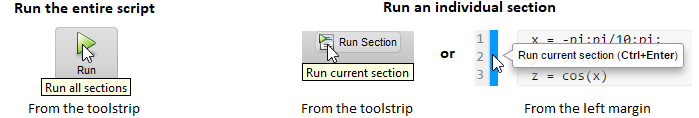

***Challenge:**** Can you find the type of weather event that occurs most often in the data?*

# Explore and Analyze Storm Events

Explore the frequency of various storm events and locations and the associated damage costs. 

clear 
load weatherEvents
head(data);

## Summarize Damage for Each Type of Weather Event

There are several events which clearly are more expensive than others (wildfires in Kansas and New Mexico, flooding in Louisiana). Also, wildfires, flooding, and tornadoes are examples of costly events which occur in multiple states.  Find summary statistics on the damage for each weather event.

eventSummary = groupsummary(data,'weathercats',{'mean','std','max'},...
    'damage_total')

eventSummary = 29×5 table
      weathercats      GroupCount    mean_damage_total    std_damage_total    max_damage_total
    _______________    __________    _________________    ________________    ________________

    Avalanche               19                  0                   0                  0      
    Blizzard               275             2.6522              20.096                240      
    Coastal Weather       2164             1.2397              18.884                500      
    Debris Flow             29             20.621              92.381                500      
    Dense Fog              533            0.16908              3.4403                 70      
    Drought                418             3.2766              10.207                 50      
    Dust Devil              11             

## Visualize the Distribution of the Damage by Event Type

We can visualize the distributions of the damage caused by various events with a [boxplot](http://www.mathworks.com/help/stats/boxplot.html). 

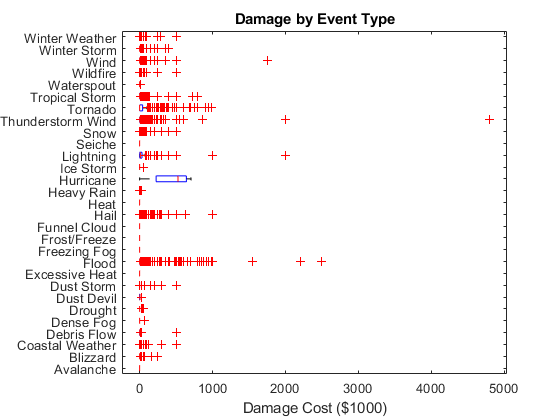

figure
boxplot(data.damage_total,data.weathercats,...
    'Orientation','horizontal')
xlabel('Damage Cost ($1000)')
title('Damage by Event Type')

Flooding, hail, wildfires and coastal weather are some of the more costly events when it comes to damage. The boxplot also shows a number of values near zero, some with many outliers and a large spread, so these additional considerations may be necessary in future modeling tasks.

## Visualize Damage Cost of Events by Location

The data contain location and storm information as well as the damage costs. Do certain states experience high damage costs because of these events? Do some events tend to cost more than others?

We can visualize the average cost of events by state with a `heatmap`. 

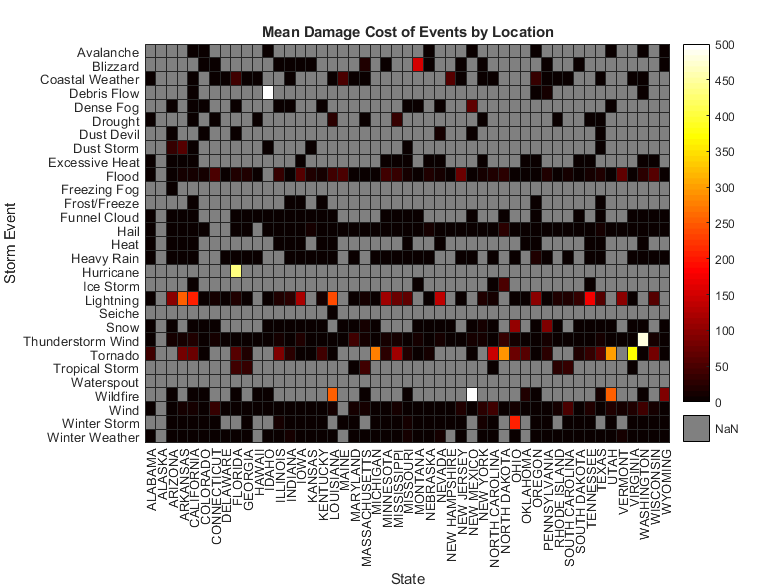

bigFigure;
h = heatmap(data,'state','weathercats',...
    'ColorVariable','damage_total');
h.Colormap = hot;
title('Mean Damage Cost of Events by Location')
xlabel('State')
ylabel('Storm Event')
h.MissingDataColor = [0.5 0.5 0.5];

## Visualize Damages from Weather Events on a Map

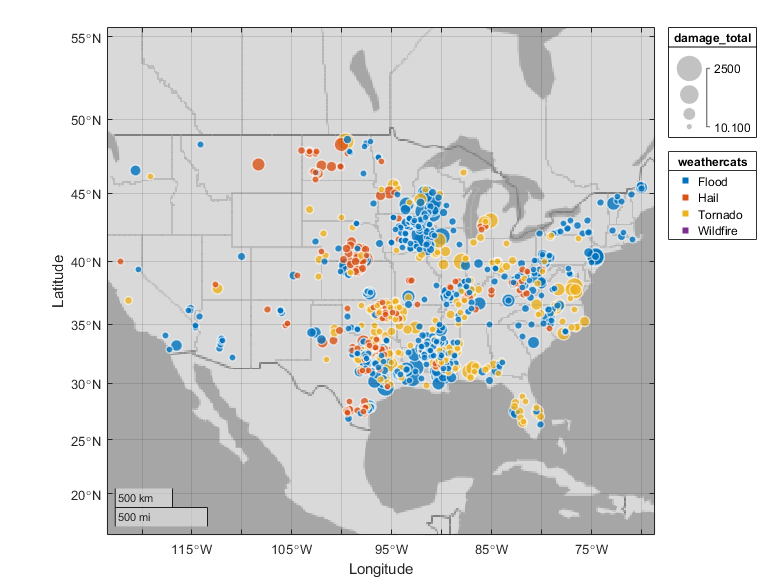

testEvents = {'Wildfire','Flood','Tornado','Hail'};
t = data(ismember(data.weathercats,testEvents) & ...
    data.damage_total > 10,:);
t.weathercats = removecats(t.weathercats);
geobubble(t,'begin_lat','begin_lon','ColorVariable','weathercats',...
    'SizeVariable','damage_total');

## Helper Functions

function f = bigFigure
    f = figure;
    f.Position = f.Position.*[1 1 1.4 1.4];
end 

*Copyright 2017-2018 The MathWorks, Inc.*